# 第四次实验

## 实验八-2

clear
% 将100个学生5门功课的成绩存入矩阵P中，进行如下处理：
% （1）分别求每门课的最高分、最低分及相应学生序号
P = 100 * rand(100,5);
[maxP, maxPindex] = max(P);
[minP, minPindex] = min(P);
sheet = [maxPindex; maxP; minPindex; minP];
table(sheet(:,1),sheet(:,2),sheet(:,3),sheet(:,4),sheet(:,5), ...
    'RowNames', {'最高分序号';'最高分';'最低分序号';'最低分'}, ...
    'VariableNames',{'第一门', '第二门', '第三门', '第四门', '第五门'})

ans = 4×5 table
                  第一门      第二门     第三门      第四门     第五门 
                 _______    _______    ______    _______    ______

    最高分序号         31          2        60         75        58
    最高分         99.859     99.837    99.876     97.887    97.387
    最低分序号         78         40         5         65         2
    最低分        0.18304    0.48138    2.2618    0.17548    0.1804


% （2）分别求每门课的平均分和标准差
meanP = mean(P);
stdP = std(P);
sheet = [meanP; stdP];
table(sheet(:,1),sheet(:,2),sheet(:,3),sheet(:,4),sheet(:,5), ...
    'RowNames', {'平均成绩';'标准差'},...
    'VariableNames',{'第一门', '第二门', '第三门', '第四门', '第五门'})

ans = 2×5 table
               第一门     第二门     第三门     第四门     第五门 
               ______    ______    ______    ______    ______

    平均成绩    44.661    52.934    50.556    47.189    50.117
    标准差      26.649    28.807    29.958    29.214     30.62


% （3）5门课总分的最高分、最低分及相应学生序号
score = sum(P,2);
[maxS, maxSindex] = max(score);
[minS, minSindex] = min(score);
sheet = [maxS minS;maxSindex minSindex];
table(sheet(:,1), sheet(:,2), ...
    'RowNames', {'成绩';'序号'}, ...
    'VariableNames',{'最高分','最低分'})

ans = 2×2 table
            最高分     最低分 
            ______    ______

    成绩    434.11    70.364
    序号        69        30


% （4）将5门课总分按从大到小顺序存入score中，相应学生序号存入num
[score, num] = sort(score, 'descend');
disp('成绩从大到小排列：')

成绩从大到小排列：


disp(reshape(round(score), 10, 10))

   434   316   299   278   265   247   233   209   183   162
   396   316   293   277   262   247   232   207   178   162
   367   313   293   275   262   247   231   207   178   159
   356   307   293   274   257   244   226   207   177   150
   350   306   290   274   256   243   224   206   174   145
   343   304   287   272   255   243   222   206   170   139
   332   303   286   271   255   242   220   204   168   139
   327   302   285   270   254   237   220   204   165   115
   319   302   282   270   253   235   215   202   163    87
   318   300   281   267   247   234   214   201   163    70



disp('相应学生序号：')

相应学生序号：


disp(reshape(num, 10, 10))

    69    90    91    56    99    29    14    45    47    93
    72    77     8    63     1    26    68    36    79    67
    76    94    55    88    98    23    17     7    51    12
    31    37    19    50    53    41     6    34    66    28
    96    87    54    21    11    20    60    27    33    40
    24     9    73    74    82    59    80    86    83    16
    75    57     3    18    61    92    89    78    95     5
    39    25    22    49    44    97    10    43    65    35
    46    85    81    62    84     4    13    38    42    52
    70    48    32    71    64    58    15     2   100    30



## 实验八-4

clear
% 某气象观测站测得某日 6:00 至 18:00 之间每隔 2 h 的室内外温度（℃）如实验表1所示。
data = [ 6    8   10   12   14   16   18;   % 时间 h
        18.0 20.0 22.0 25.0 30.0 28.0 24.0;  % 室内温度t1
        15.0 19.0 24.0 28.0 34.0 32.0 30.0]; % 室外温度t2
% 试用三次样条插值分别求出该日室内外 6:30 至 17:30 之间每隔 2 h 各点的近似温度（℃）。
target = 6.5:2:17.5;
t1 = spline(data(1,:), data(2,:), target);
t2 = spline(data(1,:), data(3,:), target);
table([target; t1; t2],'RowNames', {'时间 h';'室内温度 t1';'室外温度 t2'},'VariableNames',{'数值'})

ans = 3×1 table
                      数值    
                  ____________

    时间 h        [1×6 double]
    室内温度 t1    [1×6 double]
    室外温度 t2    [1×6 double]


## 实验八-5

clear
% 已知 lgx 在 [1, 101] 区间 10 个整数采样点的函数值如实验表 2 所示。
data = [ 1 11 21 31 41 51 61 71 81 91 101;
        0 1.0414 1.3222 1.4914 1.6128 1.7076 1.7853 1.8513 1.9085 1.9590 2.0043];
% 试求 lgx 的 5 次拟合多项式 p(x)，并绘制出 lgx 和 p(x) 在[1,101]区间的函数曲线
target = linspace(1, 101, 100);
factor = polyfit(data(1,:), data(2,:), 5);

disp(['拟合多项式为： p(x)=' num2str(factor(1)) '*x^5 +' ...
    num2str(factor(2)) '*x^4 +' ...
    num2str(factor(3)) '*x^3 +' ...
    num2str(factor(4)) '*x^2 +' ...
    num2str(factor(5)) '*x +' ...
    num2str(factor(6))])

拟合多项式为： p(x)=3.2862e-09*x^5 +-9.7975e-07*x^4 +0.00011002*x^3 +-0.005814*x^2 +0.15366*x +-0.13261


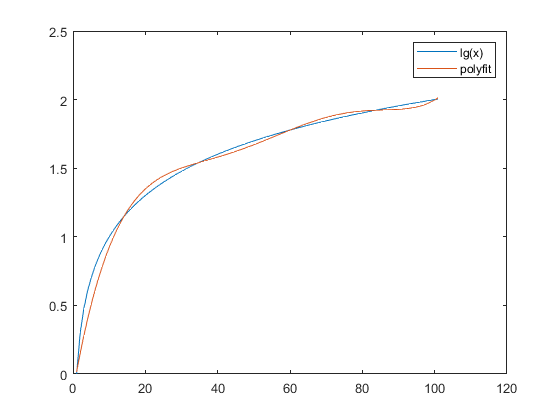

px = polyval(factor, target);
lgx = log10(target);
plot(target, lgx);
hold on
plot(target, px);
legend('lg(x)','polyfit');
hold off

## 实验九-3

clear
% 求定积分
f1 = @(t) sqrt(cos(t).^2+4*sin(2*t).^2+1)

f1 = 包含以下值的 function_handle :
    @(t)sqrt(cos(t).^2+4*sin(2*t).^2+1)


I1 = integral(f1, 0, 2*pi)

I1 = 11.4609

f2 = @(x) log(1+x)./(1+x.^2)

f2 = 包含以下值的 function_handle :
    @(x)log(1+x)./(1+x.^2)


I2 = integral(f2, 0, 1)

I2 = 0.2722

## 实验九-4

clear
% 求二重定积分
f1 = @(x,y) 1./sqrt(x.^2+y.^2)

f1 = 包含以下值的 function_handle :
    @(x,y)1./sqrt(x.^2+y.^2)


I1 = integral2(f1, 0, 1, 0, 1)

I1 = 1.7627

f2 = @(x,y) y.*sin(x) + 3*cos(y) -1

f2 = 包含以下值的 function_handle :
    @(x,y)y.*sin(x)+3*cos(y)-1


I2 = integral2(f2, 0, 2*pi, 0, pi)

I2 = -19.7392

## 实验九-5

clear
% 分别用矩形、梯形（trapz）公式计算由实验表 3 中数据给出的定积分 I = ∫ f(x)dx 从 0.3 到 1.5
data = [1       2       3       4       5       6       7;      % k
        0.3     0.5     0.7     0.9     1.1     1.3     1.5;    % x_k
        0.3895  0.6598  0.9147  1.1611  1.3971  1.6212  1.8325];% f(x_k)
% 矩形公式
s1 = sum(data(3,1:end-1).*diff(data(2,:)))

s1 = 1.2287

% 梯形公式
s2 = trapz(data(2,:), data(3,:))

s2 = 1.3730